# Country Patterns 1995

Elaborated by Natanael Bolson

Supervised by Prof. Tad Patzek and Maxim Yutkin

EGG-ANPERC-KAUST 12/2020

Description: Apply filters to find a selected country and indentify  other countries with similar characteristics for the year 1995

clc
clear
close all

% Select the year from 1990 to 2015
Year_T=1995;
% Here Run the algorithm that makes the cateogrical classification
run Categorize.m
Pop=Data_EIA_H.Population(:,yo);
Pop(Clean)=[];
% to Print
P='F' ;% 'T' prints

## China

% CH=intersect(Wat_H,intersect(Mat_N,intersect(En_H,intersect(Land_N,intersect(find(CO2_cat(:,yo)~='L'),find(Ren_cat(:,yo)~='H'))))));
CH=intersect(Wat_H,intersect(Mat_H,intersect(En_H,intersect(Land_L,intersect(find(CO2_cat(:,yo)~='L'),find(Ren_cat(:,yo)~='H'))))))

CH =     28
    29
    40
    61
   100
   102
   138



Labels(CH)

ans = 7×1 cell array
    {'China'       }
    {'Colombia'    }
    {'Ecuador'     }
    {'Indonesia'   }
    {'P. N. Guinea'}
    {'Peru'        }
    {'Vietnam'     }


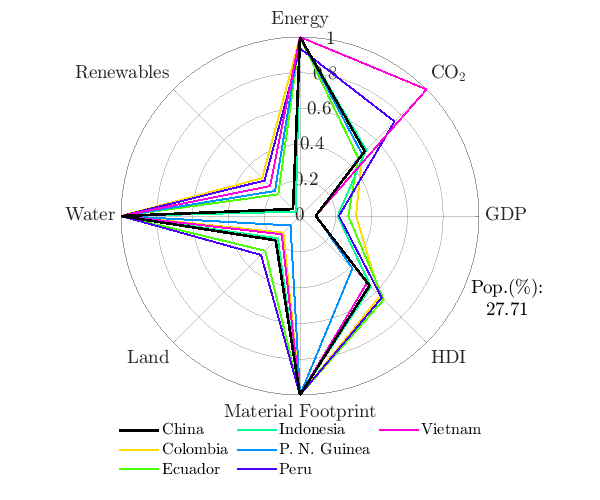

N=length(CH); 
C = hsv(N);
i=0;
figure

for n=CH'
    i=i+1;
    if n==28
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    end
end
 Values=Ind_S(28,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)

LegT=Labels(CH);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(CH,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
if P=='T'
    print('-depsc2','-r400','CH_95.eps')
end

## Russia

RU=intersect(En_H,intersect(Land_H,intersect(Wat_H,intersect(CO2_L,find(Ren_cat(:,yo)~='H')))));
Labels(RU)

ans = 5×1 cell array
    {'Argentina' }
    {'Australia' }
    {'Canada'    }
    {'Kazakhstan'}
    {'Russia'    }


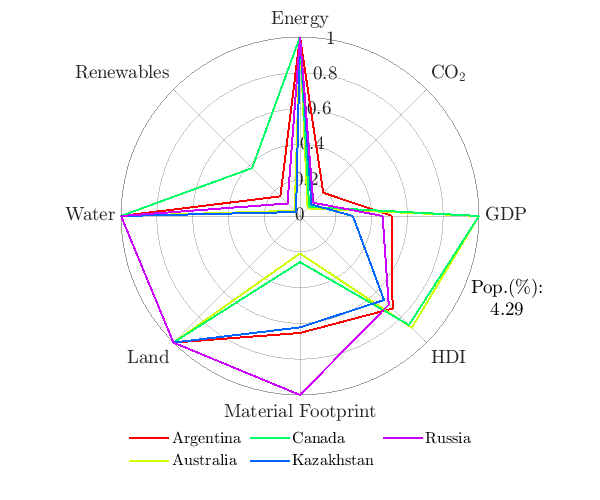

figure
N=length(RU); 
C = hsv(N);
axes('NextPlot','replacechildren', 'ColorOrder',C);
i=0;
for n=RU'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(RU);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(RU,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','RU_95.eps')
end

## India

IN=intersect(En_M,intersect(Mat_H,intersect(Wat_H,intersect(CO2_M,find(Ren_cat(:,yo)~='H')))));
Labels(IN)

ans = 3×1 cell array
    {'Burma'   }
    {'India'   }
    {'Zimbabwe'}


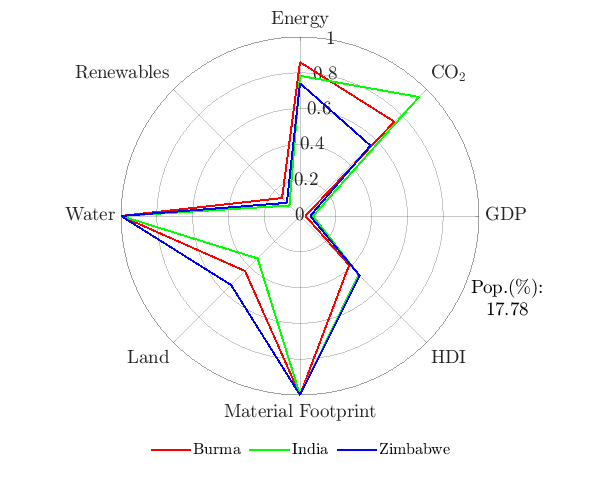

N=length(IN); 
figure
C = hsv(N);
i=0;
for n=IN'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(IN);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(IN,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','IN_95.eps')
end

## Egypt

EG=intersect(Wat_L,intersect(Mat_H,Land_L))

EG =     38
    41
    69
    81
   139


Labels(EG)

ans = 5×1 cell array
    {'Djibouti'}
    {'Egypt'   }
    {'Jordan'  }
    {'Maldives'}
    {'Yemen'   }


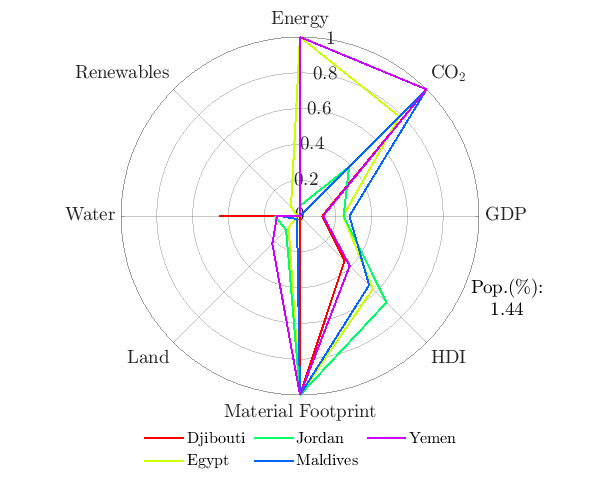

figure
N=length(EG); 
C = hsv(N);
i=0;
for n=EG'
   i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(EG);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(EG,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','EG_95.eps')
end

## USA

US=intersect(Wat_H,intersect(GDP_H,intersect(En_M,Mat_L)))

US =     37
    59
   121
   135


Labels(US)

ans = 4×1 cell array
    {'Denmark'      }
    {'Iceland'      }
    {'Sweden'       }
    {'United States'}


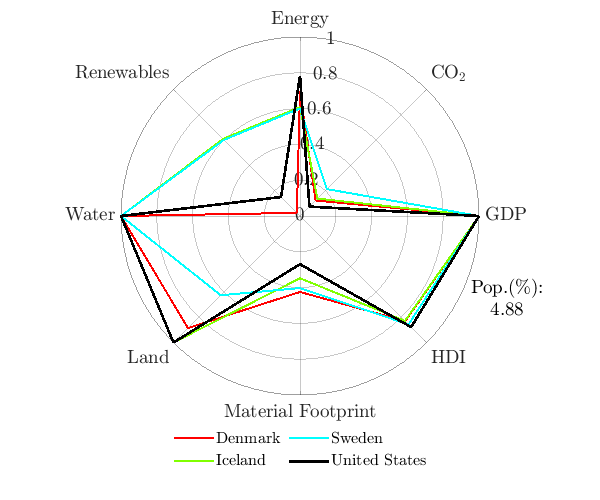

figure()
N=length(US); 
C = hsv(N);
i=0;
for n=US'
    i=i+1;
    if n==135
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    end
end

LegT=Labels(US);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(US,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
if P=='T'
    print('-depsc2','-r400','US_95.eps')
end

## Brazil

BR=intersect(CO2_L,intersect(GDP_L,intersect(En_M,intersect(Wat_H,intersect(Land_M,find(Ren_cat(:,yo)~='H'))))))

BR =      9
    17
    18
   107


Labels(BR)

ans = 4×1 cell array
    {'Azerbaijan'}
    {'Botswana'  }
    {'Brazil'    }
    {'Romania'   }


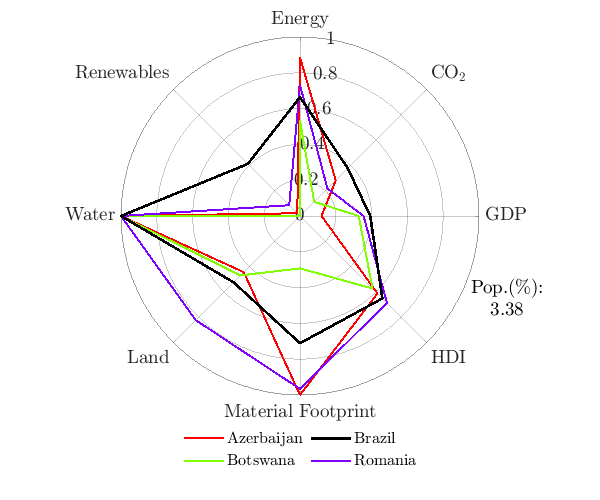

figure()
N=length(BR); 
C = hsv(N);
i=0;
for n=BR'
    i=i+1;
    if n==18
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    end
end
 Values=Ind_S(18,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
LegT=Labels(BR);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(BR,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
if P=='F'
    print('-depsc2','-r400','BR_95.eps')
end

## Indonesia

IND=intersect(Mat_H,intersect(CO2_M,intersect(En_H,intersect(Land_L,Wat_H))));
Labels(IND)

ans = 6×1 cell array
    {'China'       }
    {'Colombia'    }
    {'Ecuador'     }
    {'Indonesia'   }
    {'P. N. Guinea'}
    {'Peru'        }


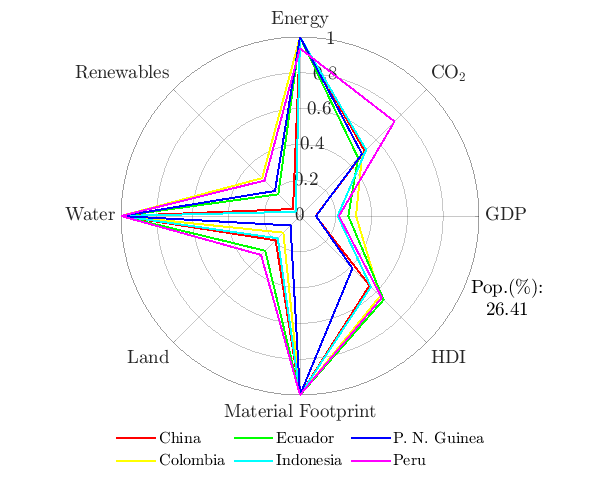

figure()
N=length(IND); 
C = hsv(N);
i=0;
for n=IND'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(IND);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(IND,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','IND_95.eps')
end

## Mexico

ME=intersect(Mat_H,intersect(CO2_L,intersect(En_H,intersect(Wat_H,intersect(find(Land_cat(:,yo)~="L"),find(GDP_cat(:,yo)=='M'))))))

ME =     48
    86
   108


Labels(ME)

ans = 3×1 cell array
    {'Gabon' }
    {'Mexico'}
    {'Russia'}


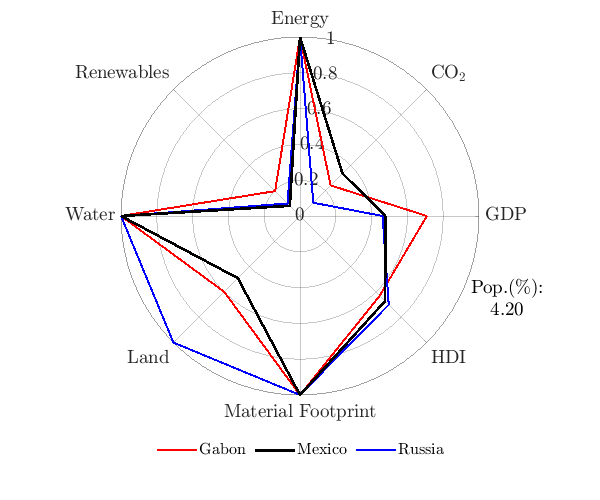

figure()
N=length(ME); 
C = hsv(N);
i=0;
for n=ME'
   i=i+1;
   if n==86
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
   end
end

       Values=Ind_S(86,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    
LegT=Labels(ME');
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(ME,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
if P=='T'
    print('-depsc2','-r400','ME_95.eps')
end

## Japan

JP=intersect(En_L,intersect(HDI_H,intersect(GDP_H,intersect(Wat_H,Land_L))))

JP =      8
    50
    66
    68
   122


Labels(JP)

ans = 5×1 cell array
    {'Austria'    }
    {'Germany'    }
    {'Italy'      }
    {'Japan'      }
    {'Switzerland'}


figure()
N=length(JP); 
C = hsv(N);
i=0;
for n=JP'
    i=i+1;
    if n==68
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    end
end
 Values=Ind_S(68,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)

LegT=Labels(JP);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(JP,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
if P=='T'
    print('-depsc2','-r400','JP_95.eps')
end

## Saudi Arabia

SA=intersect(En_H,intersect(Wat_L,GDP_H))

SA =     10
    72
   106
   111
   133


Labels(SA)

ans = 5×1 cell array
    {'Bahrain'             }
    {'Kuwait'              }
    {'Qatar'               }
    {'Saudi Arabia'        }
    {'United Arab Emirates'}


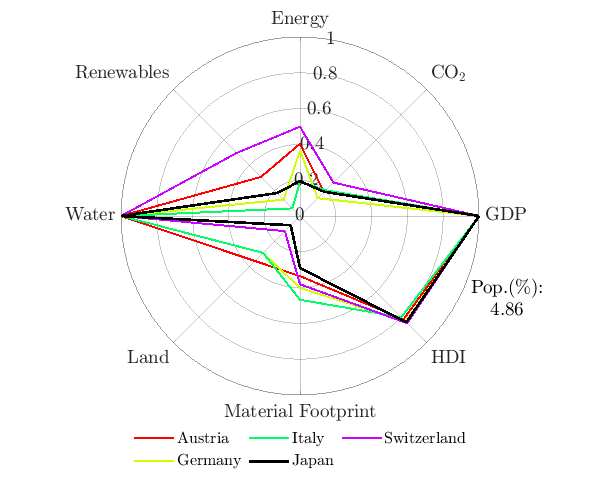

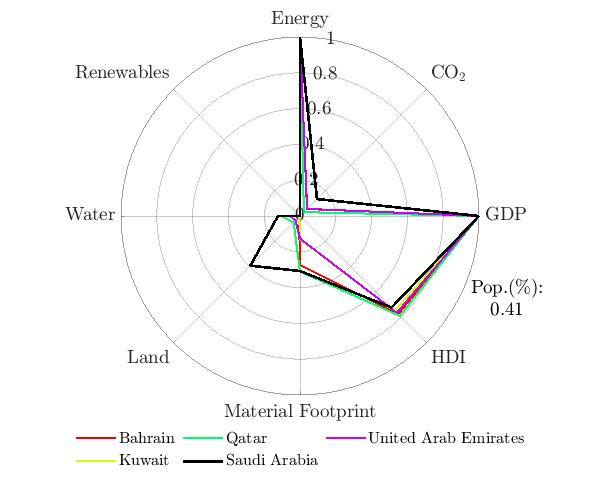

N=length(SA); 
C = hsv(N);
i=0;
figure()

for n=SA'
    i=i+1;
    if n==111
       Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    hold on 
    else
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    end
    end
   
       Values=Ind_S(111,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','k','linewidth',2)
    

LegT=Labels(SA);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(SA,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
if P=='T'
    print('-depsc2','-r400','KS_95.eps')
end

## Algeria

% AL=intersect(find(Exp_cat(:,yo)~='L'),intersect(Wat_L,intersect(Mat_H,intersect(find(CO2_cat(:,yo)~='L'),find(Land_cat(:,yo)~='H')))));
AL=intersect(find(Exp_cat(:,yo)~='L'),intersect(Wat_L,intersect(Mat_H,intersect(find(CO2_cat(:,yo)~='‍H'),find(Land_cat(:,yo)~='H')))));

Labels(AL) 

ans = 7×1 cell array
    {'Algeria' }
    {'Egypt'   }
    {'Libya'   }
    {'Pakistan'}
    {'Syria'   }
    {'Tunisia' }
    {'Yemen'   }


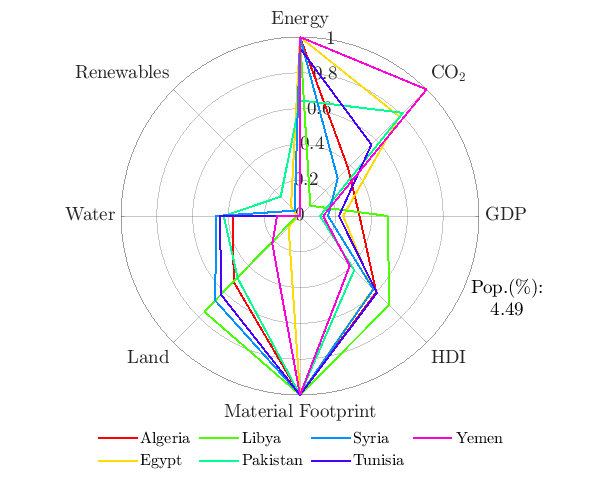

N=length(AL); 
C = hsv(N);
i=0;
figure()

for n=AL'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(AL);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',4,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(AL,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','AL_95.eps')
end

## Argetina

AR=intersect(En_H,intersect(Wat_H,intersect(Land_H,intersect(Ren_L,find(Mat_cat(:,yo)~='L')))));
AR=intersect(En_H,intersect(Wat_H,intersect(Land_H,find(Ren_cat(:,yo)~='H'))));
Labels(AR)

ans = 5×1 cell array
    {'Argentina' }
    {'Australia' }
    {'Canada'    }
    {'Kazakhstan'}
    {'Russia'    }


N=length(AR); 
C = hsv(N);
i=0;
figure()

for n=AR'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(AR);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(AR,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','AR_95.eps')
end

## Bangladesh

BA=intersect(find(CO2_cat(:,yo)~='L'),intersect(Land_L,intersect(find(Exp_cat(:,yo)~='L'),intersect(find(Water_cat(:,yo)~='L'),intersect(Ren_L,GDP_L)))));
Labels(BA)

ans = 7×1 cell array
    {'Bangladesh'  }
    {'China'       }
    {'Ecuador'     }
    {'India'       }
    {'Indonesia'   }
    {'P. N. Guinea'}
    {'Vietnam'     }


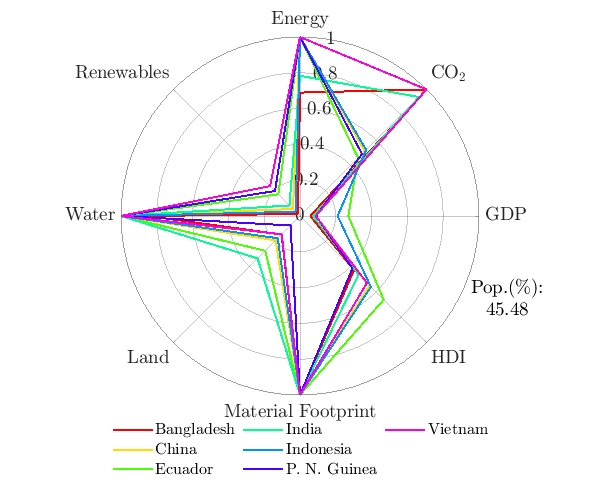

N=length(BA); 
C = hsv(N);
i=0;
figure()

for n=BA'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

end

LegT=Labels(BA);
ax = gca;
axPos = ax.Position;
ax.Position = axPos+ [0 0.05 0 0];
legend(LegT,'Position',[0.45 0.05 0.1 0.1],'FontSize', 12,'NumColumns',3,...
    'box','off','interpreter','latex')
set(gcf,'Position',[0 0 600 500])
Pop_C=nansum(Pop(setdiff(BA,1)))/Pop(1)*100;
SP=sprintf('%.2f',Pop_C);
annotation('textbox', [0.845 0.45 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','BA_95.eps')
end